# TD3 Agent Evaluation for Narnia with PWM Duty Cycle Output

slxFile = "Narnia_eval_model";
open_system(slxFile);
run("../Narnia_systemIdentification/estim_by_physics.mlx"); %Load system's parameters

actInfo = rlNumericSpec([1 1],...
    LowerLimit=0,...
    UpperLimit=100,...%Use smaller D's upper bound to make training faster
    Name="PWM duty cycle", ...
    Description="%", ...
    DataType='uint8');
obsInfo = rlNumericSpec([6 1],...
    LowerLimit=[-inf -inf -inf -inf -inf -inf]',...
    UpperLimit=[ inf  inf  inf  inf  inf  inf]',...
    Name = "observation",...
    Description = "integrated Ta error, Ta error, Ta, Ta-To, Tf, load, 3-step-ahead To");
simEnv = rlSimulinkEnv(slxFile, slxFile+"/Thermostat/RL Agent", obsInfo, actInfo);

Ts = 0.25; %Agent sampling time (hours)
Tf = 24; %Always run for 1 full day
P = 0.2; %PWM period (hours)

% load("bl8c_oj_uint8_3k6_lqr.mat");
simOpts = rlSimulationOptions(MaxSteps=ceil(Tf/Ts),StopOnError="on");
simEnv.ResetFcn = @(in)testCase03(in);
experiences = sim(simEnv, bl8c_oj_uint8_3k6_lqr, simOpts);

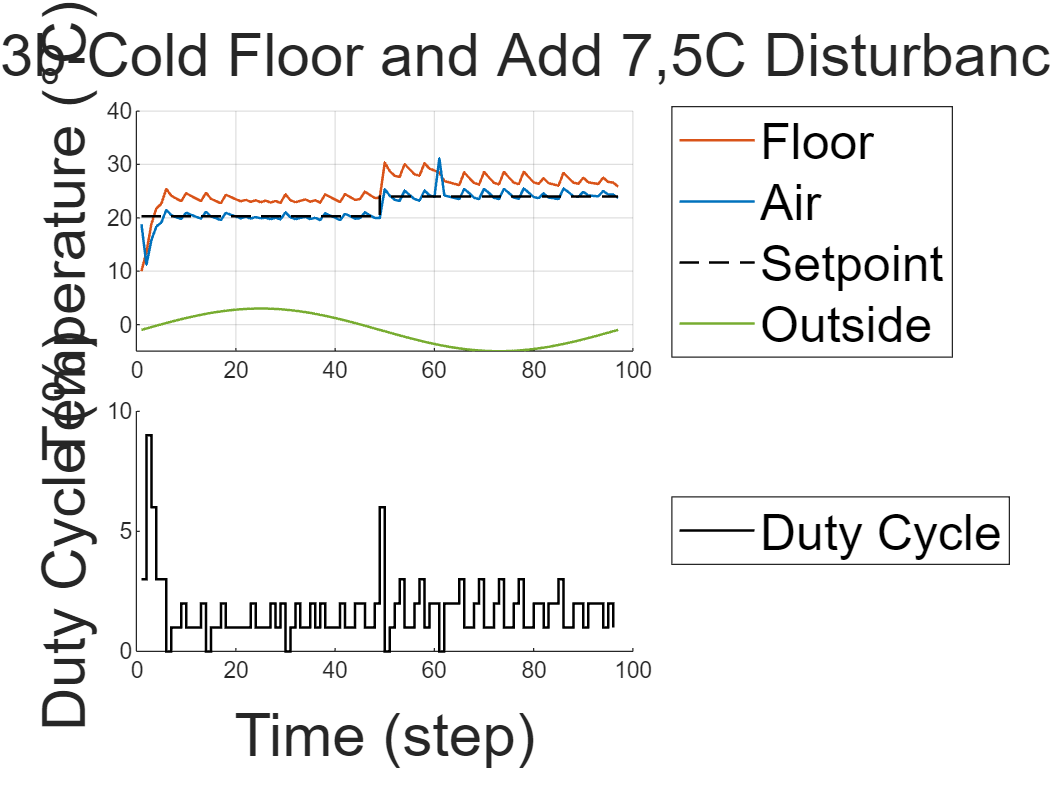

Ta = squeeze(experiences.Observation.observation.Data(3,:,:));
Tref = squeeze(experiences.Observation.observation.Data(2,:,:)) + Ta;
Tout = -(squeeze(experiences.Observation.observation.Data(4,:,:)) - Ta);
Tf = squeeze(experiences.Observation.observation.Data(5,:,:));
u = squeeze(experiences.Action.PWMDutyCycle.Data);
% Ta(48:end,:)=Ta(48:end,:)-0.2;Edge Case 1b-Cool a Warm Room
export_agent_evaluation("Edge Case 3b-Cold Floor and Add 7,5C Disturbance", Tref, Ta-0.2, Tf, Tout, u);

% function in = testCase01(in)    
%     %Randomize average outside temperature
%     slxFile = "Narnia_eval_model";
%     T0 = 22;
%     load = 6;
%     T_out = 17;
%     %Set outside temp as initial values for Ta and Tf
%     blk = slxFile+"/Outside Temp";
%     in = setBlockParameter(in,blk,Value=num2str(T_out));
%     T0K = [T0+273;T0+273];
%     in = setBlockParameter(in, slxFile+"/Narnia/Cont Integrator",...
%         InitialCondition=string(T0K));
%     in = setBlockParameter(in, slxFile+"/Mean Temp per Ts",...
%         x0=string(T0));
%     %Set load
%     blk = slxFile+"/Heater/Load";    
%     % in = setBlockParameter(in,blk,Value=num2str(load));
% end

function in = testCase01(in)    
    %Randomize average outside temperature
    slxFile = "Narnia_eval_model";
    T0 = 22;
    load = 10;
    T_out = 17;
    %Set outside temp as initial values for Ta and Tf
    blk = slxFile+"/Outside Temp";
    in = setBlockParameter(in,blk,Value=num2str(T_out));
    T0K = [T0+273;T0+273];
    in = setBlockParameter(in, slxFile+"/Narnia/Cont Integrator",...
        InitialCondition=string(T0K));
    in = setBlockParameter(in, slxFile+"/Mean Temp per Ts",...
        x0=string(T0));
    %Set load
    blk = slxFile+"/Heater/Load";
    in = setBlockParameter(in,blk,Value=num2str(load));
end
function in = testCase02(in)    
    %Randomize average outside temperature
    slxFile = "Narnia_eval_model";
    T0 = 22;
    load = 15;
    T_out = 17;
    %Set outside temp as initial values for Ta and Tf
    blk = slxFile+"/Outside Temp";
    in = setBlockParameter(in,blk,Value=num2str(T_out));
    T0K = [T0+273;T0+273];
    in = setBlockParameter(in, slxFile+"/Narnia/Cont Integrator",...
        InitialCondition=string(T0K));
    in = setBlockParameter(in, slxFile+"/Mean Temp per Ts",...
        x0=string(T0));
    %Set load
    blk = slxFile+"/Heater/Load";    
    in = setBlockParameter(in,blk,Value=num2str(load));
end

function in = testCase03(in)    
    %Randomize average outside temperature
    slxFile = "Narnia_eval_model";
    T0 = 22;
    load = 15;
    T_out = 12;
    %Set outside temp as initial values for Ta and Tf
    blk = slxFile+"/Outside Temp";
    in = setBlockParameter(in,blk,Value=num2str(T_out));
    T0K = [T0+273;T0+273];
    in = setBlockParameter(in, slxFile+"/Narnia/Cont Integrator",...
        InitialCondition=string(T0K));
    in = setBlockParameter(in, slxFile+"/Mean Temp per Ts",...
        x0=string(T0));
    %Set load
    blk = slxFile+"/Heater/Load";    
    in = setBlockParameter(in,blk,Value=num2str(load));
end